Copyright 2018 The MathWorks, Inc.

# **Analysis of Tire Test Data **

This script processes tire test data from acceleration and brake tests and returns the Magic Formula coefficients for both a longitudinal and lateral model. This code matches the data structure provided by the Formula SAE Tire Test Consortium [www.fsaettc.org](www.fsaettc.org).

## Acknowledgements

- We want to thank the “Formula SAE Tire Test Consortium” (FASE TTC, [www.fsaettc.org](https://localhost:31515/toolbox/matlab/codetools/liveeditor/www.fsaettc.org)) and the “Calspan Tire Research Facility” (TIRF) for their support and permission to use two de-identified tire data sets. Note that you may obtain access to FSAE TTC (see *FSAE_TTC_agreement.pdf*).

- We gratefully acknowledge the contribution from [Marc Russouw](https://www.linkedin.com/in/marc-russouw-28119688/), former member of Monash Motorsport. Marc presented his approach in an episode of the [MATLAB and Simulink Racing Lounge](http://www.mathworks.com/racinglounge) named "[Tire Modeling - Extracting Results from a Large Data Set](https://www.mathworks.com/videos/matlab-and-simulink-racing-lounge-tire-modeling-extracting-results-from-a-large-data-set-98129.html)" and shared his code. We developed starting with his state, documented and published the code.

Disclaimer

Our goal in creating this script is to provide a tool to analyze large sets of tire data. While a large amount of time was spent ensuring this script is correct we cannot guarantee results accuracy. Please let us know about any flaws in the workflow and inaccuracies you might experience.

**Modeling Process**

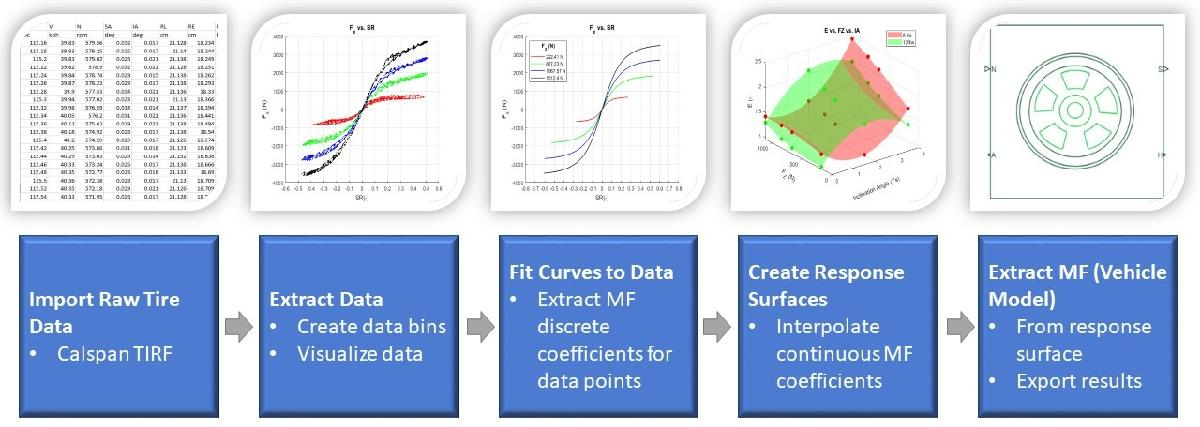

Nomenclature of quantities / units in tire data files are summarized here for reference purpose: 

- AT: Ambient Temperature [degC]

- B,C,D,E: Magic Formula Coefficients

- ET: Elapsed Time [s]

- FX: Traction Force [N]

- FY: Lateral Force [N]

- FZ: Vertical Force [N]

- IA: Inclination Angle [deg]

- MX: Overturning Moment [Nm]

- MZ: Aligning Moment [Nm]

- N: Wheel rotational speed [rpm]

- NFX: Normal Force in X [normalized against vectorial load]

- NFY: Normal Force in Y [normalized against vectorial load]

- P: Pressure [kPa]

- RE: Effective Radius [cm]

- RL: Loaded Radius [cm]

- RST: Road Surface Temperature [degC]

- SA: Slip Angle [deg]

- SR: Slip Ratio [-]         

- TSTC: Tire Surface Temperature Center [degC]

- TSTI: Tire Surface Temperature Inner [degC]

- TSTO: Tire Surface Temperature Outer [degC]

-  V: Forward Speed of Axle [m/s]  

## Initialization

clear;
clc;
close all;

addpath(fullfile(pwd,'Functions'));

datamode = LongOrLat(); % Choose longetudinal or lateral mode
[fileid, pathname] = uigetfile({'*.mat;*.dat'},'File Selector');
if( isa(fileid, 'double') && isequal(fileid, 0) )
    % No file was chosen, so we return
    return
end

[AT, ET, FX, FY, FZ, IA, MX, MZ, N, NFX, NFY, P, RE, RL, RST, SA, SR, TSTC, TSTI, TSTO, V]...
    = ImportRawData( fullfile(pathname, fileid) );

Functions for converting between lbf and N

lbf2N = @(lbf)lbf*4.4482216152605;
N2lbf = @(N)N/4.4482216152605;

Functions for converting between kPa and psi

psi2kPa = @(psi)psi/0.145037737730217;
kPa2psi = @(kPa)kPa*0.145037737730217;

## Identify data points tested

Tires are tested following pre-defined test routines. To calculate the Magic Formula coefficients it is important to identify test points of **normal force, tire pressure and inclination angle**. The correct test values can be identified in the following figures:

**Normal force**: 

You can see in the example below that the tire was tested under different normal forces. The Magic Formula parameters depend on the normal force FZ of the tire, where the normal force should be in Newtons. The values are around 50,100,150,250 pounds (1pound = 4.448N). We save those values to create our normal force bins later. 

**Figure to identify the Variation of FZ:**

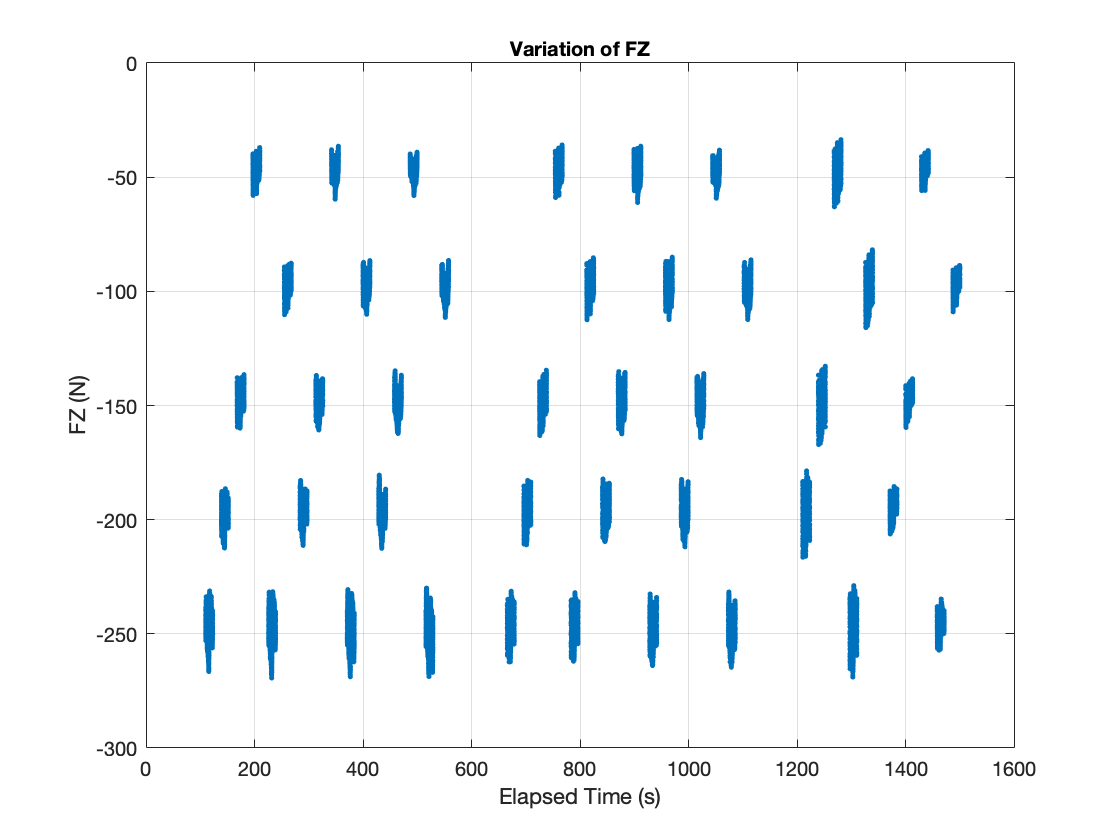

figure
plot(ET,FZ/4.448,'.'); 
grid on
xlabel('Elapsed Time (s)');
ylabel('FZ (N)');
title('Variation of FZ','FontSize',10);

[countsFZ,edgesFZ] = histcounts(N2lbf(FZ));
[~,locsFZ] = findpeaks([countsFZ(2), countsFZ, countsFZ(end-1)]);

**Tire pressure:**

Tire pressure is often denoted in kPa but to visualize the data it was converted to pound-force per square inch (1 kPa = 0.145 psi). 

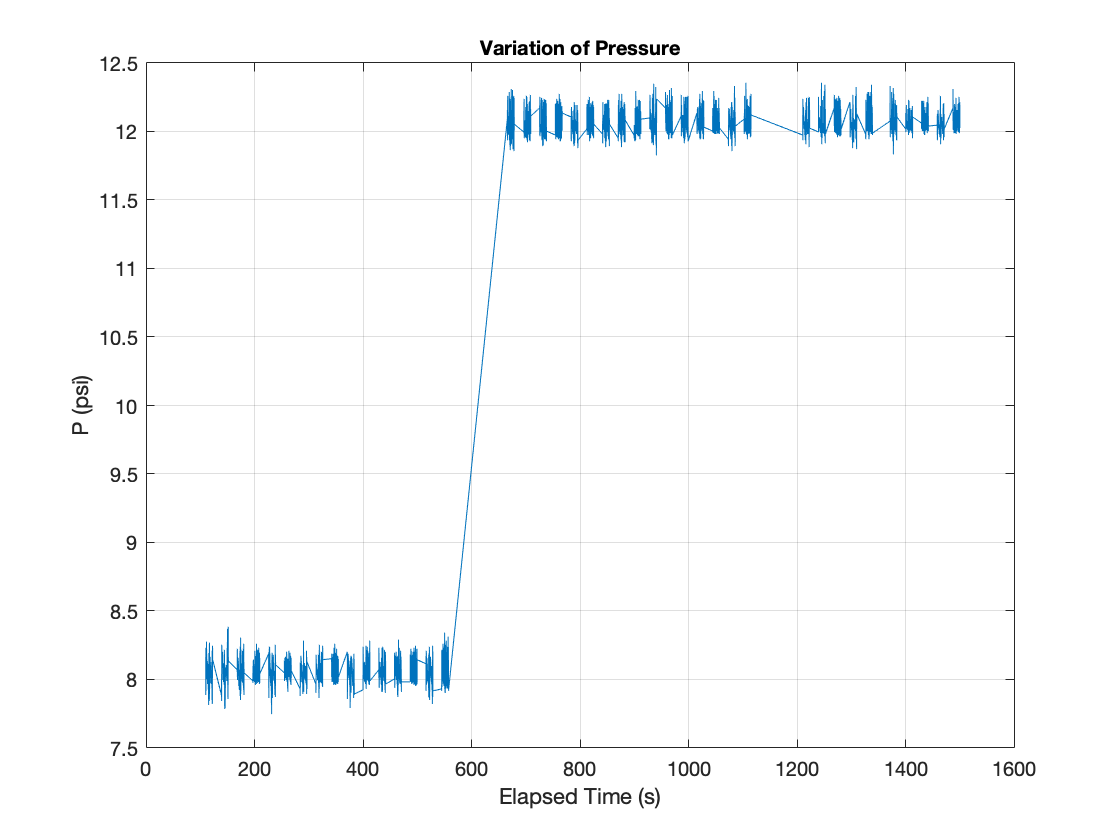

figure 
plot(ET,0.145*P);
xlabel('Elapsed Time (s)');
ylabel('P (psi)');
grid on
title('Variation of Pressure','FontSize',10);

[countsP,edgesP] = histcounts(kPa2psi(P));
[~,locsP] = findpeaks([countsP(2), countsP, countsP(end-1)]);

**Inclin****ation Angle: **

The inclination angle is the angle of the wheel relative to the surface.

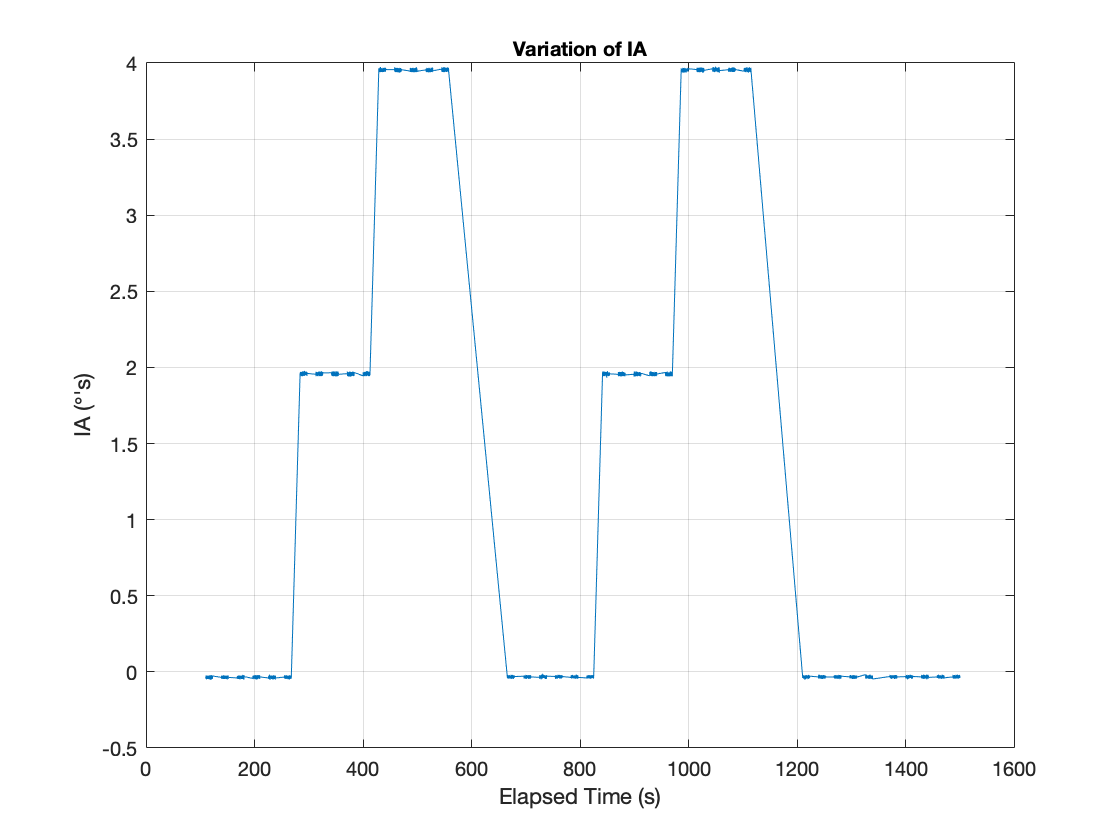

figure 
plot(ET,IA);
xlabel('Elapsed Time (s)');
ylabel('IA ({\circ}''s)');
grid on
title('Variation of IA','FontSize',10);

[countsIA,edgesIA] = histcounts(IA);
[~,locsIA] = findpeaks([countsIA(2), countsIA, countsIA(end-1)]);

**Note: **If you want to check the data that was imported is proper comment out the code after this point and check the graphs above

## Create bins for data

To group data into bins, logic statements are used. Those bins describe which values of normal force, pressure or inclination angle have been tested. Tolerances are applied to accomodate measured data into bins.

**Note: **The choice of test values has to be done manually.

FZ_binvalues = lbf2N(unique(round(abs(edgesFZ(locsFZ)))));
P_binvalues = unique(round(edgesP(locsP)));
IA_binvalues = unique(round(edgesIA(locsIA)));

if( isempty(FZ_binvalues) || isempty(P_binvalues) || isempty(IA_binvalues) )
    error('One or more of the *_binValues arrays was empty.')
end

**Pressure bins **

P_eps = 0.8;  % Pressure tolerance (psi)
P_bin = kPa2psi(P)>(P_binvalues-P_eps-0.3)&kPa2psi(P)<(P_binvalues+P_eps); %(psi)

**Note**: Using implicit expansion (available from release 2016b on). Suggested to use repmat() when working with older releases.

**I****nclination angle bin**

IA_eps = 0.2; % Inclination angle tolerance (deg)
IA_bin = (IA>IA_binvalues-IA_eps)&(IA<IA_binvalues+IA_eps); %(deg)

**Normal force bin**

FZ_eps1 = lbf2N(35); % Normal force tolerance (N)
FZ_bin = abs(FZ)>((FZ_binvalues-FZ_eps1))&abs(FZ)<((FZ_binvalues+FZ_eps1)); %(N)

**Zero slip bin**

The zero slip bin is used where the slip values should be close to zero but these values depends on whether the model is longitudinal or lateral. If the data is longitudinal slip angles are used and slip ratio for lateral.

if datamode == 1
    S_0 = (-1<SA)&(SA<1);
else
    S_0 = (-1<SR)&(SR<1);
end

**Create surface points**

For plotting purposes a meshgrid for normal force and IA bin values is created.

[IA_mat,FZ_mat] = meshgrid(IA_binvalues,FZ_binvalues);

## Preallocate memory

For performance reasons memory is preallocated for variables that change size during loops.

A = cell(length(P_binvalues),length(IA_binvalues),length(FZ_binvalues));
[S_binfzia, F_binfzia, NF_binfzia, ET_binfzia, FZ_binfzia, IA_binfzia, ...
    MX_binfzia, MZ_binfzia, CS_fzia, mu_fzia, S_H_fzia, S_V_fzia, S_bar_fzia, ...
    F_bar_fzia, B_fzia, C_fzia, D_fzia, E_fzia, F_M, S_M] = deal(A);

B = cell(length(P_binvalues), 1);
[B_P, C_P, D_P, E_P, S_S_P, S_V_P, mu_P, S_H_P, CS_P, S_H_surf_IA_P, ...
    S_V_surf_IA_P, Mu_surf_IA_P, CS_surf_IA_P, B_surf_IA_P, C_surf_IA_P, ...
    D_surf_IA_P, E_surf_IA_P] = deal(B);

## Data analysis

To obtain Magic Formula coefficients for varying data points the code loops through tire pressure, normal force and inclination angle bins.

**Loop through pressure bins**

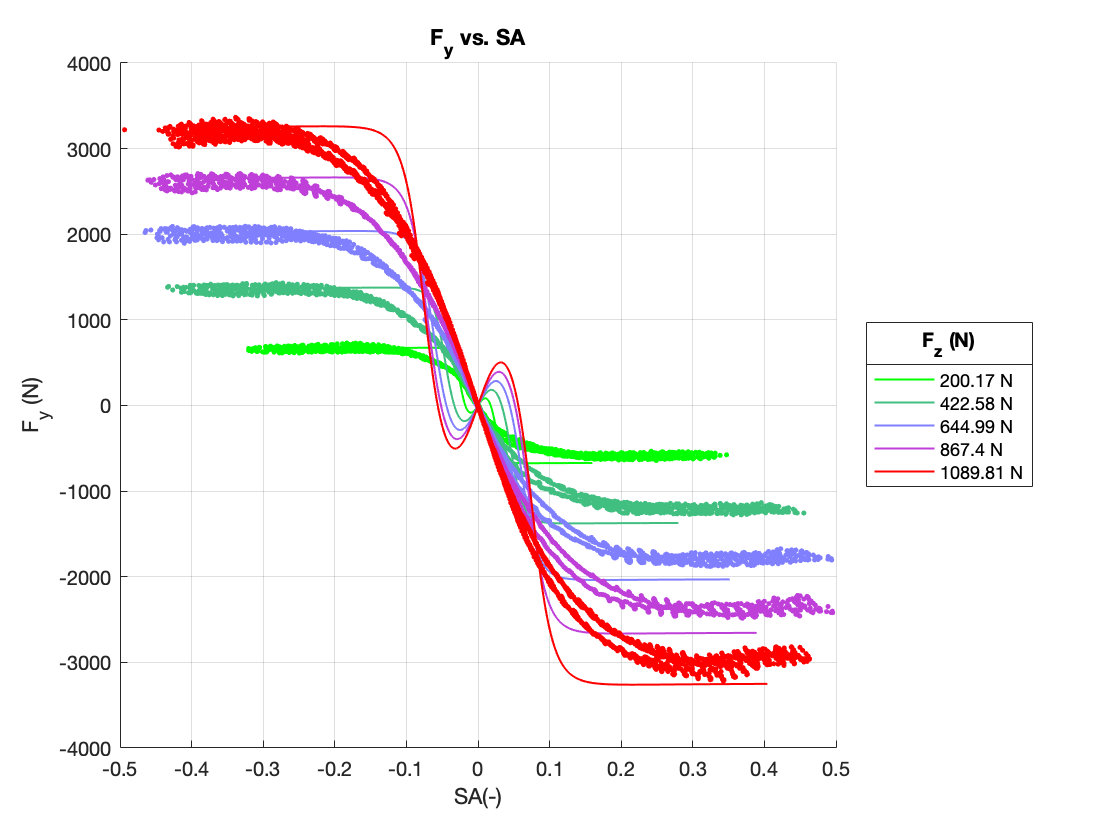

for i=1:length(P_binvalues)
    for m=1:size(FZ_bin,2)
        for n=1:size(IA_bin,2)
            validIdx = FZ_bin(:,m) & P_bin(:,i) & IA_bin(:,n) & S_0;
            ET_binfzia{i,n,m}  =  ET(validIdx);  % Time Bins
            FZ_binfzia{i,n,m}  =  FZ(validIdx);  % Vertical Load bins
            IA_binfzia{i,n,m}  =  IA(validIdx);  % Inclination Angle bins
            MX_binfzia{i,n,m}  =  MX(validIdx);  % Overturning Moment bins
            MZ_binfzia{i,n,m}  =  MZ(validIdx);  % Aligning Moment bins
            
            if datamode == 1
                F_binfzia{i,n,m}  =  FX(validIdx);  % Logitudinal Force Bins
                NF_binfzia{i,n,m} =  NFX(validIdx); % Force Coefficient bins
                S_binfzia{i,n,m}  =  SR(validIdx);  % Slip Ratio Bins
            else
                F_binfzia{i,n,m}  =  FY(validIdx);  % Lateral Force Bins
                NF_binfzia{i,n,m} =  NFY(validIdx); % Force Coefficient bins
                S_binfzia{i,n,m}  =  SA(validIdx);  % Slip Angle Bins
            end

**Nondimensional Scaling**

After bins have been created NonDimTrans() and MagicFit() are used to calculate the Magic Formula coefficients.

- NonDimTrans() takes the bin values and normalizes them to nondimensional force and nondimensional slip ratio

- MagicFit()  fits Magic Formula to the data 

**Note:** These are functions defined within the 03_Function folder.

For pure longitudinal slip the normalized longitudinal Force ${\bar{F} }_x$ and normalized slip ratio $\bar{S}$ is defined as:   


$${\bar{F} }_x =\frac{F_x }{\mu_x Z}$$
             
$${\bar{S} } =\frac{k_x S}{\mu_x Z}$$
 

Where:

- $k_x$ is the initial slope of longitudinal force

- $\mu_x$ is the friction coefficient

- $Z$ is the load

- $S$ is the slip ratio

Slip ratio is defined as percentage of the difference between the surface speed of the wheel compared to the speed between axis and road surface.

$S=\frac{\Omega *\textrm{RE}}{V}-1$     $\Omega$: wheel angular velocity (radians per second)

*As defined in the Race Car Vehicle Dynamics book by Milliken

For the lateral  the normalized lateral force $\bar{F_y }$ and normalized slip angle $\alpha^‾$ are defined as:

 
$$\bar{F_y } =\frac{F_y }{\mu_y Z}$$
         
$$\alpha^‾ =\frac{\mathrm{C}\;\tan \;\alpha }{\mu_y Z}$$
 

Where:

- $\mu_y$ is the lateral friction coefficient

- $\alpha$ is the slip angle

- $C$ is the cornering stiffness

    Slip angle is defined as the angle between the direction in which the tire is going and the direction towards it is actually pointed.

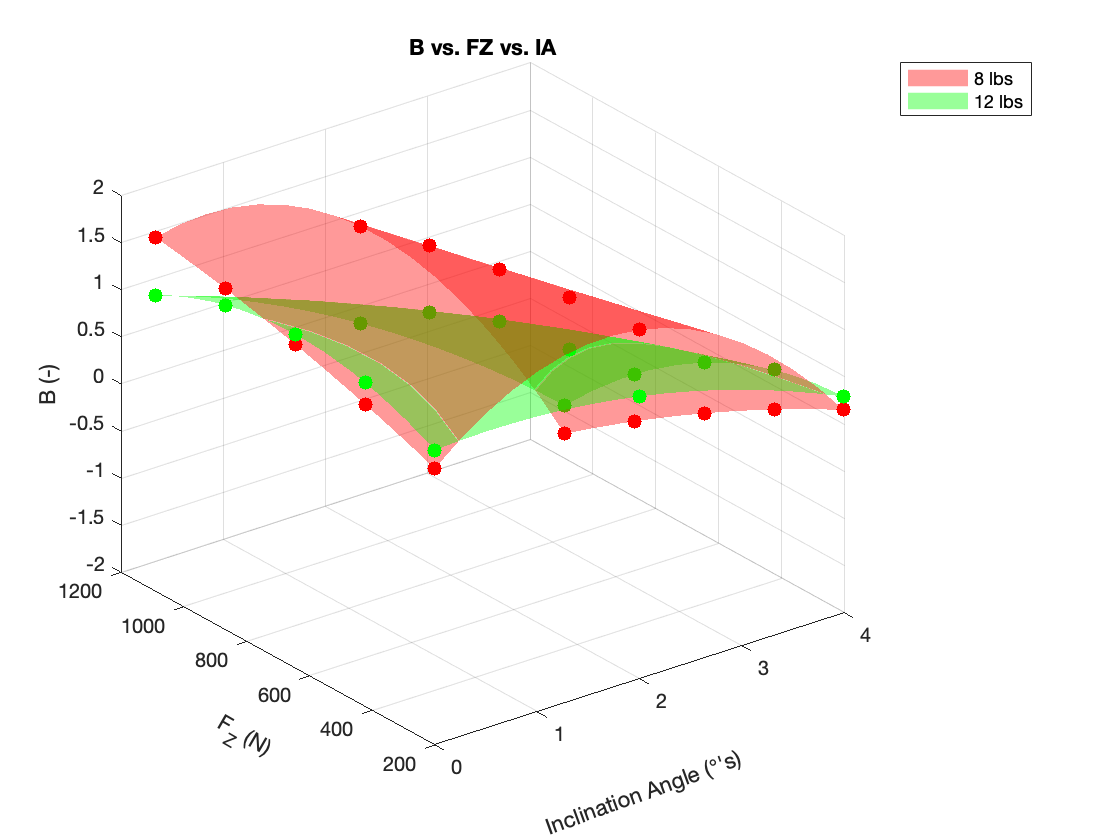

             [CS_fzia{i,n,m}, mu_fzia{i,n,m}, S_H_fzia{i,n,m}, ...

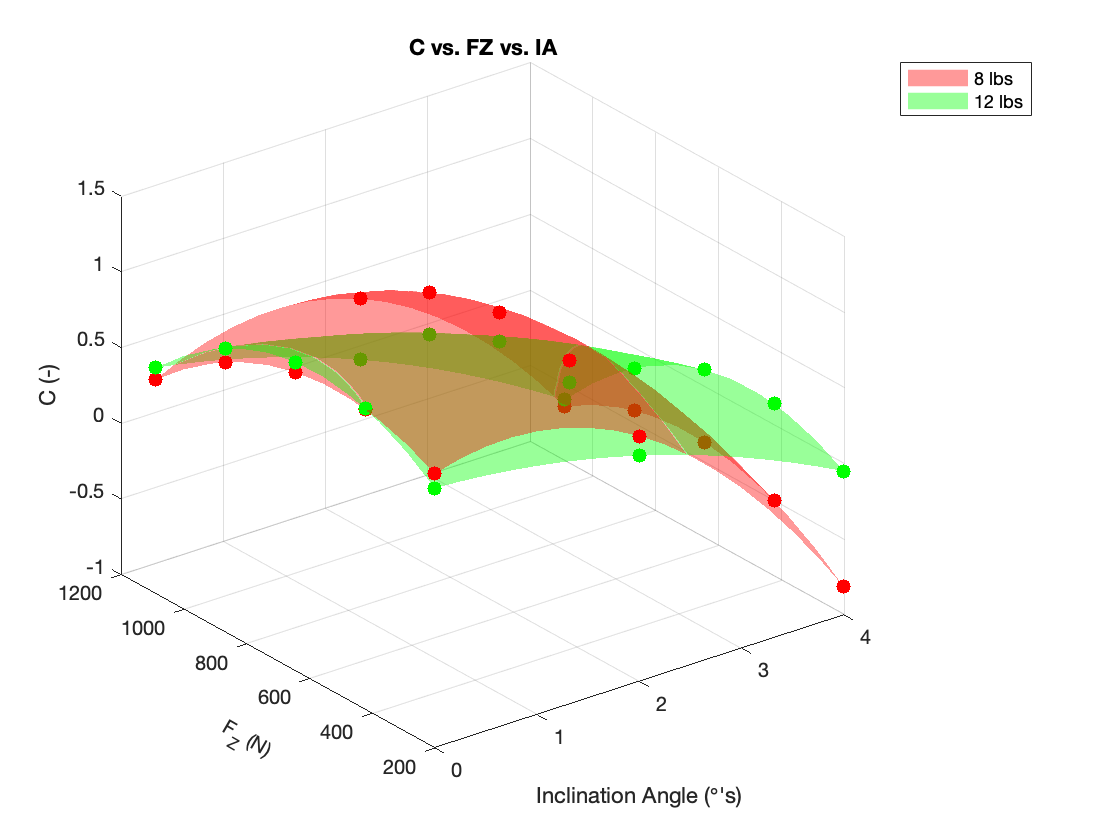

             S_V_fzia{i,n,m}, S_bar_fzia{i,n,m}, F_bar_fzia{i,n,m}] = ...

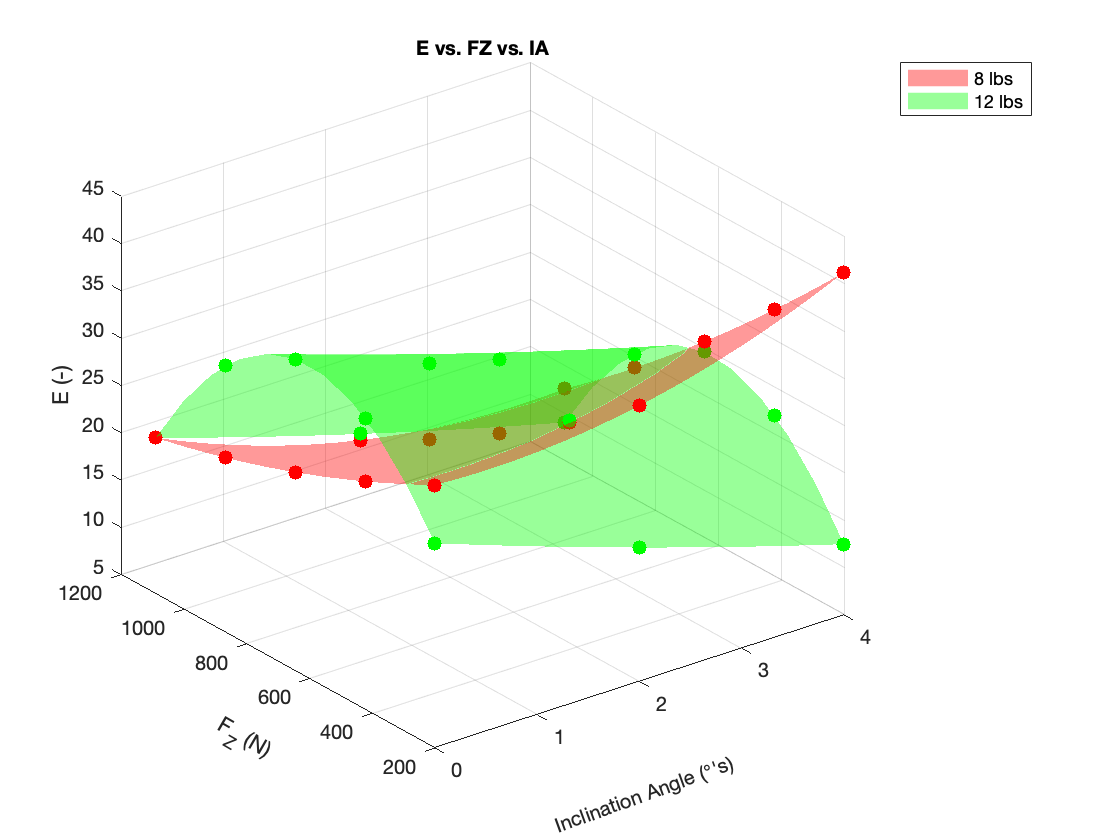

                NonDimTrans( F_binfzia{i,n,m}, NF_binfzia{i,n,m}, ...
                    S_binfzia{i,n,m}, ET_binfzia{i,n,m}, FZ_binfzia{i,n,m});        

**Magic Formula fit**

The Magic Formula is defined below with the following constraints: normalization of the peak magnitude and normalization of the slope through the origin:


$$\bar{F_x } =\sin \left\lbrace \frac{1}{B_x }\arctan \left(B_x \left(1-E_x \right)\bar{S} +E_x *\arctan \left(B_x \bar{S} \right)\right)\right\rbrace$$



$$D=1$$
     


$$\textrm{BCD}=1$$
   

            [B_fzia{i,n,m}, C_fzia{i,n,m}, D_fzia{i,n,m}, E_fzia{i,n,m}] = ...
                MagicFit(F_bar_fzia{i,n,m}, S_bar_fzia{i,n,m}); 
        end
    end

**MATLAB data**** ty****pe conversion**

Cell arrays are partly transformed into numeric arrays for convenience.

B_P,C_P,D_P represent discrete Magic Formula parameters for all bin values. E.g. B_P{1} represents B coefficient at pressure 8 psi.  

    B_P{i}   = permute(cell2mat(B_fzia(i,:,:)),[3,2,1])';
    C_P{i}   = permute(cell2mat(C_fzia(i,:,:)),[3,2,1])';
    D_P{i}   = permute(cell2mat(D_fzia(i,:,:)),[3,2,1])';
    E_P{i}   = permute(cell2mat(E_fzia(i,:,:)),[3,2,1])';
    S_S_P{i} = permute(cell2mat(CS_fzia(i,:,:)),[3,2,1])' ./FZ_binvalues;
    S_V_P{i} = permute(cell2mat(S_V_fzia(i,:,:)),[3,2,1])'./FZ_binvalues;
    mu_P{i}  = permute(cell2mat(mu_fzia(i,:,:)),[3,2,1])';
    S_H_P{i} = permute(cell2mat(S_H_fzia(i,:,:)),[3,2,1])'./FZ_binvalues;
    CS_P{i}  = permute(cell2mat(CS_fzia(i,:,:)),[3,2,1])';

**Response surface fit**

Second-order surfaces are fitted to the discrete data points. Testing tires can be resource intensive and hence only discrete values are tested. Fitting allows to interpolate results.

    x = IA_binvalues;
    y = FZ_binvalues;
    
    S_H_surf_IA_P{i} = ResponseSurf(S_H_P{i},y,x,2);
    S_V_surf_IA_P{i} = ResponseSurf(S_V_P{i},y,x,2);
    Mu_surf_IA_P{i}  = ResponseSurf(mu_P{i},y,x,2);
    CS_surf_IA_P{i}  = ResponseSurf(CS_P{i},y,x,2);
    B_surf_IA_P{i}   = ResponseSurf(B_P{i},y,x,2);
    C_surf_IA_P{i}   = ResponseSurf(C_P{i},y,x,2);
    D_surf_IA_P{i}   = ResponseSurf(D_P{i},y,x,2);
    E_surf_IA_P{i}   = ResponseSurf(E_P{i},y,x,2);

**Plot longitudinal force over slip ratio**

Plots that show longitudinal force FX over slip ratio SR for longitudinal data or lateral force FY over slip angle SA for lateral data are generated below. It shows how well the Magic Formula was fitted to the data points.

Force and slip values were still nondimensional and are transformed into dimensional quantities using MagicOutput().

    Slip_fit = -3:0.01:3;
    
    for m=1:length(FZ_binvalues)
        for n=1:length(IA_binvalues)        
            [F_M{i,n,m},S_M{i,n,m}] = MagicOutput(MagicFormula([B_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(n)),...
                E_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m))],Slip_fit),...
                Slip_fit,Mu_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),...
                FZ_binvalues(m),CS_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),datamode);
            

Plotting Magic Formula plot output to see how the data was fitted.

            if(i==1)
                if(m==1 && n==1)
                    figure
                    ax1 = axes;
                    hold on
                    if datamode == 1
                        FvsS_Title = 'F_x vs. SR';
                        yLab = 'F_x (N)'; xLab = 'SR(-)';
                    else
                        FvsS_Title = 'F_y vs. SA';
                        yLab = 'F_y (N)'; xLab = 'SA(-)';
                    end
                    title(FvsS_Title);
                    xlabel(xLab);
                    ylabel(yLab);
                    grid on
                end
                if(n==1)
                    [Ft,SRt]= MagicOutput(F_bar_fzia{i,n,m},S_bar_fzia{i,n,m},...
                        Mu_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),...
                        FZ_binvalues(m),CS_surf_IA_P{i}(IA_binvalues(n),FZ_binvalues(m)),datamode);
                    
                    % Plotting the Line fit and the Raw Data Points
                        color = [(linspace(0,1,5))' (linspace(1,0,5))' ([0 .5 1 0.85 0])'];
                        % Matrix was created to have the same color betweeen data and fit line. Change the amount of values if more colors are needed.
                    plot(ax1,SRt,Ft,'.','Color',[color(m,1) (color(m,2)) color(m,3)],'HandleVisibility','off');
                    FZ_binvalues_r = round(FZ_binvalues,2);
                    plot(S_M{i,n,m}',F_M{i,n,m}','Color',[color(m,1) color(m,2) color(m,3)],'LineWidth',1,...
                        'DisplayName',[mat2str(FZ_binvalues_r(m)) ' N']);  
                end     
            end
        end
    end
    
    % Creating the legend for figure. 
    h = legend(ax1,'show');
    set(h,'Location','eastoutside');
    htitle = get(h,'Title');
    set(htitle,'String','F_z (N)','FontSize',10);

**Plot B,C,D,E  o****ver FZ a****n****d IA**

Surface plots of B,C,D,E each in one figure. Note as explained before D will always be 1 as of constraints. A point on the surface represents a coefficient at a certain inclination angle, pressure and normal force. 

    if(i==1)
        % Defining figures:
        [x_plot,y_plot] = meshgrid(0:0.25:4,linspace(FZ_binvalues(1),FZ_binvalues(end),11));      
        figure
            ax2 = axes;
            hold on
            grid on
            title('B vs. FZ vs. IA');
            xlabel('Inclination Angle ({\circ}''s)','Rotation',20);
            ylabel('F_Z (N)','Rotation',-30);
%             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
            zlabel('B (-)');
            view([-37.5 30]);
        figure
            ax3 = axes;
            hold on
            grid on 
            title('C vs. FZ vs. IA');
            xlabel('Inclination Angle ({\circ}''s)');
            ylabel('F_Z (N)','FontSize',10,'Rotation',-30);
%             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
            zlabel('C (-)');
            view([-37.5 30]);
% %  Ommitted due to assumption D = 1
%         figure
%             ax4 = axes;
%             hold on
%             grid on 
%             title('D vs. FZ vs. IA','FontSize',10);
%             xlabel('Inclination Angle ({\circ}''s)','Rotation',20);
%             ylabel('F_Z (N)','Rotation',-30);
%             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
%             zlabel('D (-)','FontSize',10);
%             view([-37.5 30]);
        figure
            ax5 = axes;
            hold on
            grid on 
            title('E vs. FZ vs. IA','FontSize',10);
            xlabel('Inclination Angle ({\circ}''s)','FontSize',10,'Rotation',20);
            ylabel('F_Z (N)','Rotation',-30);
%             ylim([0 2000]); zlim([0 3.5]); % To make graph limits the same uncomment this line and edit values
            zlabel('E (-)');
            view([-37.5 30]);
    end
    
    plot3(ax2,IA_mat,FZ_mat,B_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
        'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
    mesh(ax2,x_plot,y_plot,(B_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
        'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
    plot3(ax3,IA_mat,FZ_mat,C_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
        'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
    mesh(ax3,x_plot,y_plot,(C_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
        'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
%     plot3(ax4,IA_mat,FZ_mat,D_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
%         'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
%     mesh(ax4,x_plot,y_plot,(D_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
%         'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binValues(i)) ' lbs']);
    plot3(ax5,IA_mat,FZ_mat,E_surf_IA_P{i}(IA_mat,FZ_mat),'.','MarkerSize',25,...
        'MarkerEdgeColor',[i==1 i==2 i==3],'HandleVisibility','off');
    mesh(ax5,x_plot,y_plot,(E_surf_IA_P{i}(x_plot,y_plot)),'EdgeColor','none','LineWidth',2,...
        'FaceAlpha',0.4,'FaceColor',[i==1 i==2 i==3],'DisplayName',[mat2str(P_binvalues(i)) ' lbs']);
end
hLegend(1) = legend(ax2,'show');
hLegend(2) = legend(ax3,'show');
% hLegend(3) = legend(ax4,'show');
hLegend(4) = legend(ax5,'show');

## Data export

% Data Value points
IA_vect = IA_binvalues;
FZ_vect = FZ_binvalues;

% n-D-LookUp Table Output
bp3d1 = FZ_binvalues;
bp3d2 = IA_binvalues;
bp3d3 = P_binvalues;

B_Lookup3d_map = B_surf_IA_P{1}(IA_mat,FZ_mat);
C_Lookup3d_map = C_surf_IA_P{1}(IA_mat,FZ_mat);
D_Lookup3d_map = D_surf_IA_P{1}(IA_mat,FZ_mat);
E_Lookup3d_map = E_surf_IA_P{1}(IA_mat,FZ_mat);

for Pidx = 2:numel(P_binvalues)
    B_Lookup3d_map = cat(3, B_Lookup3d_map, B_surf_IA_P{Pidx}(IA_mat,FZ_mat));
    C_Lookup3d_map = cat(3, C_Lookup3d_map, C_surf_IA_P{Pidx}(IA_mat,FZ_mat));
    D_Lookup3d_map = cat(3, D_Lookup3d_map, D_surf_IA_P{Pidx}(IA_mat,FZ_mat));
    E_Lookup3d_map = cat(3, E_Lookup3d_map, E_surf_IA_P{Pidx}(IA_mat,FZ_mat));
end

Saving data points and surfaces for further use. MATLAB sfit objects can be plotted directly with e.g. plot(B_surf_IA_P{1}); 

[pathstr,name,ext] = fileparts(fileid);
save(fullfile(pwd,'Results',[name '_MagicFormula_datapoints.mat']),...
    'bp3d1', 'bp3d2', 'bp3d3', 'B_Lookup3d_map', 'C_Lookup3d_map', 'D_Lookup3d_map', 'E_Lookup3d_map');
save( fullfile(pwd,'Results',[name '_MagicFormula_datasurfaces.mat']),...
    'B_surf_IA_P','C_surf_IA_P','D_surf_IA_P','E_surf_IA_P');